# 21960197 向平 Assignment 4

# Ex 3.1.3

Write a Matlab function polyinterp.m that takes as input a set of (x,y) interpolatingpoints and another x0, and outputs y0, the value of the interpolating polynomial at x0. The first line of the file should be function y0 = polyinterp(x,y,x0), where x and y are input vectors of data points. Your function may call newtdd from Program 3.1 and nest from Chapter 0, and may be structured similarly to Program 3.2, but without the graphics.Demonstrate that your function works.

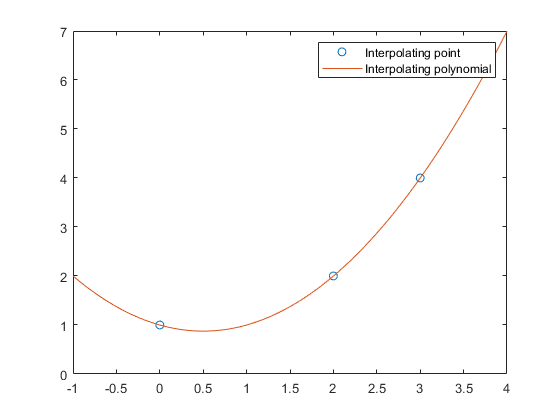

x0 = [0 2 3];
y0 = [1 2 4];
x = -1:0.01:4;
y = polyinterp(x0,y0,x);
plot(x0,y0,'o',x,y);
legend('Interpolating point','Interpolating polynomial')

The marker 'o' in the figure above represents the interpolating points, and the red line represents the corresponding interpolated polynomials, and it demonstrate the value of the interpolating polynomial on the intervals [-1, 4]. From the above plot, we can see the programme works well.

# Ex 3.2.1

(a) Use the method of divided differences to find the degree 4 interpolating polynomial $P_4 \left(x\right)$ for the data (0.6,1.433329), (0.7,1.632316),  0.8,1.896481), (0.9,2.247908), and (1.0,2.718282). 

% call the newtdd function
x0 = [0.6 0.7 0.8 0.9 1.0];
y0 = [1.433329 1.632316 1.896481 2.247908 2.718282];
% in nested form
coef = newtdd(x0, y0, 4+1)

coef =     1.4333    1.9899    3.2589    3.6807    4.0004


(b) Calculate $P_4 \left(0\ldotp 82\right)$ and $P_4 \left(0\ldotp 98\right)$. 

y_82 = nest(4, coef, 0.82, x0);
fprintf('P_4(0.82)=%.6f',y_82)

P_4(0.82)=1.958910

y_98 = nest(4, coef, 0.98, x0);
fprintf('P_4(0.98)=%.6f',y_98)

P_4(0.98)=2.612848

(c) The preceding data come from the function $f\left(x\right)=e^{x^2 }$ . Use the interpolation error formula to find upper bounds for the error at $x=0\ldotp 82$ and $x=0\ldotp 98$, and compare the bounds with the actual error. 

syms x;
syms r;     
f(r) = exp(r^2);
f5(r) = diff(f(r), 5)

$$f5(r) = 120\,r\,{\mathrm{e}}^{r^{2}}+160\,r^{3}\,{\mathrm{e}}^{r^{2}}+32\,r^{5}\,{\mathrm{e}}^{r^{2}}$$

Here r represents $\xi$.

error_bound(x) = (x-0.6)*(x-0.7)*(x-0.8)*(x-0.9)*(x-1.0)/factorial(5)*f5(r)

$$error\_bound(x) = \frac{\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)\,\left(x-\frac{7}{10}\right)\,\left(x-\frac{9}{10}\right)\,\left(120\,r\,{\mathrm{e}}^{r^{2}}+160\,r^{3}\,{\mathrm{e}}^{r^{2}}+32\,r^{5}\,{\mathrm{e}}^{r^{2}}\right)}{120}$$

x_points = 0.5:0.01:1;
f5_max = max(f5(x_points))

$$f5\_max = 312\,\mathrm{e}$$

error_bound_absolu(x) = abs((x-0.6)*(x-0.7)*(x-0.8)*(x-0.9)*(x-1.0)/factorial(5)*f5_max)

$$error\_bound\_absolu(x) = \frac{13\,\mathrm{e}\,\left|\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)\,\left(x-\frac{7}{10}\right)\,\left(x-\frac{9}{10}\right)\right|}{5}$$

format short;
actual_error_82 = abs(eval(y_82-f(0.82)))

actual_error_82 = 2.3349e-05

bound_error_82 = eval(error_bound_absolu(0.82))

bound_error_82 = 5.3736e-05

**When **$x=0\ldotp 82,|e^{{0\ldotp 82}^2 } -P_4 \left(0\ldotp 82\right)|\le 5\ldotp 3736\times {10}^{-5}$**, and in fact **$\left|e^{{0\ldotp 82}^2 } -P_4 \left(0\ldotp 82\right)\right|\approx 2\ldotp 3349\times {10}^{-5}$** , which is smaller than the bound.**

actual_error_98 = abs(eval(y_98-f(0.98)))

actual_error_98 = 1.0661e-04


bound_error_98 = eval(error_bound_absolu(0.98))

bound_error_98 = 2.1657e-04

**When **$x=0\ldotp 98,\left|e^{{0\ldotp 98}^2 } -P_4 \left(0\ldotp 98\right)\right|\le 2\ldotp 1657\times {10}^{-4}$**, and in fact **$\left|e^{{0\ldotp 98}^2 } -P_4 \left(0\ldotp 98\right)\right|\approx 1\ldotp 0661\times {10}^{-4}$** , which is also smaller than the bound**.

(d) Plot the actual interpolation error $P\left(x\right)-e^{x^2 }$ on the intervals [.5,1] and [0,2].

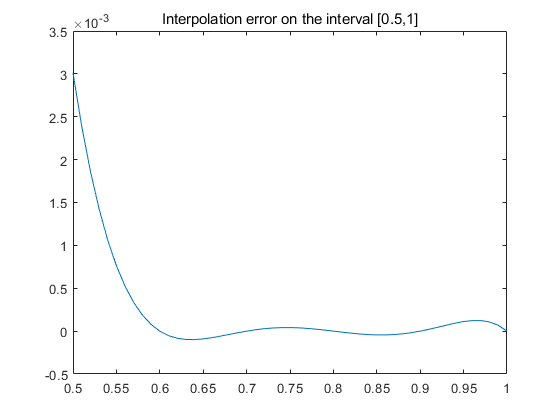

interval_1 = 0.5:0.01:1;
interval_2 = 0:0.01:2;
f5_1 = nest(4, coef, interval_1, x0);
f5_2 = nest(4, coef, interval_2, x0);
actual_error_1 = eval(f5_1-f(interval_1));
actual_error_2 = eval(f5_2-f(interval_2));
% plot of the interpolation error on the interval [0.5,1]
plot(interval_1, actual_error_1);
title('Interpolation error on the interval [0.5,1]')

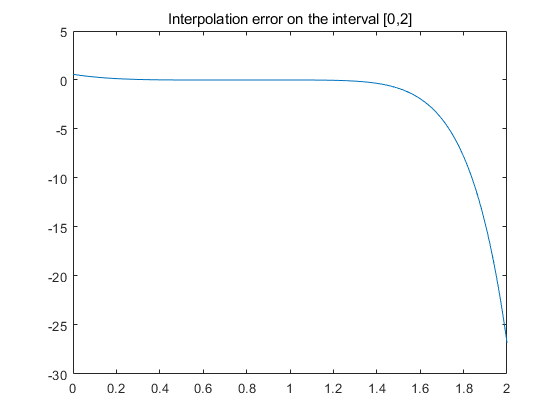

% plot of the interpolation error on the interval [0,2]
plot(interval_2, actual_error_2);
title('Interpolation error on the interval [0,2]')

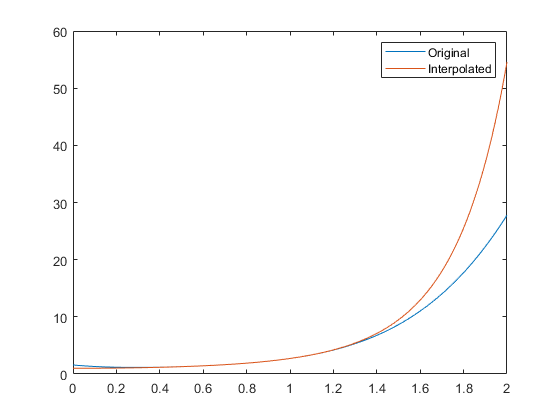

% plot of the original function f(x) and the interpolation polynomial P_5(x)
plot(interval_2, f5_2, interval_2, f(interval_2));
legend('Original','Interpolated')

**From the above plots, we can observe that the actual errors near the interpolating points are tiny, and when far away from these interpolated points, the error increases quickly.**

# Ex 3.3.2

Build a Matlab program to evaluate the cosine function correct to 10 decimal places using Chebyshev interpolation. Start by interpolating on a fundamental domain [0,π/2], and extend your answer to inputs between $-{10}^4$ and ${10}^4$. You may want to use some of the Matlab code written in this chapter.

syms n;
error_bound(n) = pi^n/(factorial(n)*2^(3*n-1));
eval(error_bound(10))

ans = 4.8069e-11

So n = 10 meets the criterion for 10 correct decimal places.

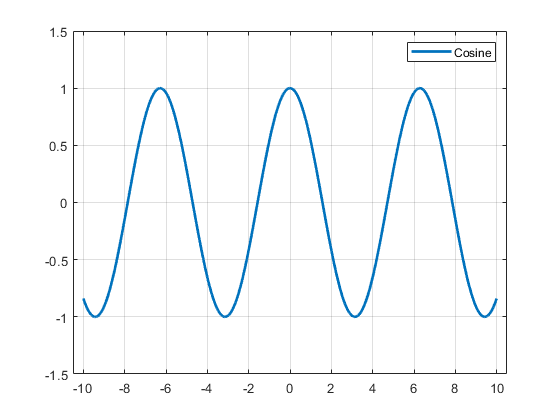

x = -10:0.01:10;
y = zeros(size(x));
%x = 2*pi-0.01;
[~,count] = size(x);
for i = 1:count
   y(i) = cos2(x(i)); 
end
plot(x, y, 'LineWidth', 2);
legend('Cosine');
axis([-10.5, 10.5, -1.5, 1.5]);
grid on;

# Ex 3.4.1

Find the equations and plot the natural cubic spline that interpolates the data points (a) (0,3), (1,5), (2,4), (3,1) 

% a
x_a = [0, 1, 2, 3];
y_a = [3, 5, 4, 1];
coef = splinecoef(x_a, y_a);
n = length(x_a);
x1 = [];
y1 = [];
k = 100;
syms x;
for i=1:n-1
    xs = linspace(x_a(i), x_a(i+1), k);
    s(x) = y_a(i)+coef(i,1)*(x-x_a(i))+coef(i,2)*(x-x_a(i))^2+coef(i,3)*(x-x_a(i))^3;
    ys = s(xs);
    x1 = [x1; xs(1:k)'];
    y1 = [y1; ys(1:k)'];
    fprintf('S%d(x)=',i);
    disp(eval(s));
    fprintf('on interval [%d,%d].\n',x_a(i),x_a(i+1));
end

S1(x)=

$$-\frac{2\,x^{3}}{3}+\frac{8\,x}{3}+3$$

on interval [0,1].


S2(x)=

$$\frac{2\,x}{3}-2\,{\left(x-1\right)}^{2}+\frac{{\left(x-1\right)}^{3}}{3}+\frac{13}{3}$$

on interval [1,2].


S3(x)=

$$\frac{{\left(x-2\right)}^{3}}{3}-{\left(x-2\right)}^{2}-\frac{7\,x}{3}+\frac{26}{3}$$

on interval [2,3].


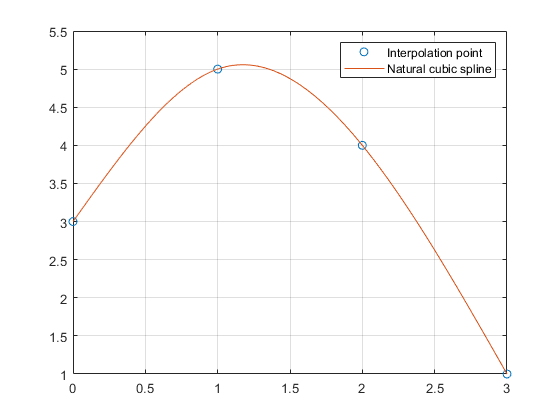

x1 = [x1; x_a(end)];
y1 = [y1; y_a(end)];
plot(x_a,y_a,'o',x1,y1);
grid on;
legend('Interpolation point','Natural cubic spline');

**The above results demonstrate the Natural Cubic Spline functions and corresponding curve, and from the above plot we can observe the obtained Natural Cubic Spline fits the interpolating points well. **

(b) (−1,3), (0,5), (3,1), (4,1), (5,1).

% a
x_b = [-1, 0, 3, 4, 5];
y_b = [3, 5, 1, 1, 1];
coef = splinecoef(x_b, y_b);
n = length(x_b);
x1 = [];
y1 = [];
k = 100;
syms x;
for i=1:n-1
    xs = linspace(x_b(i), x_b(i+1), k);
    s(x) = y_b(i)+coef(i,1)*(x-x_b(i))+coef(i,2)*(x-x_b(i))^2+coef(i,3)*(x-x_b(i))^3;
    ys = s(xs);
    x1 = [x1; xs(1:k)'];
    y1 = [y1; ys(1:k)'];
    fprintf('S%d(x)=',i);
    disp(eval(s));    
    fprintf('on interval [%d,%d].\n',x_b(i),x_b(i+1));
end

S1(x)=

$$\frac{815\,x}{318}-\frac{179\,{\left(x+1\right)}^{3}}{318}+\frac{1769}{318}$$

on interval [-1,0].


S2(x)=

$$\frac{101\,x^{3}}{318}-\frac{179\,x^{2}}{106}+\frac{139\,x}{159}+5$$

on interval [0,3].


S3(x)=

$$\frac{62\,{\left(x-3\right)}^{2}}{53}-\frac{217\,x}{318}-\frac{155\,{\left(x-3\right)}^{3}}{318}+\frac{323}{106}$$

on interval [3,4].


S4(x)=

$$\frac{31\,x}{159}-\frac{31\,{\left(x-4\right)}^{2}}{106}+\frac{31\,{\left(x-4\right)}^{3}}{318}+\frac{35}{159}$$

on interval [4,5].


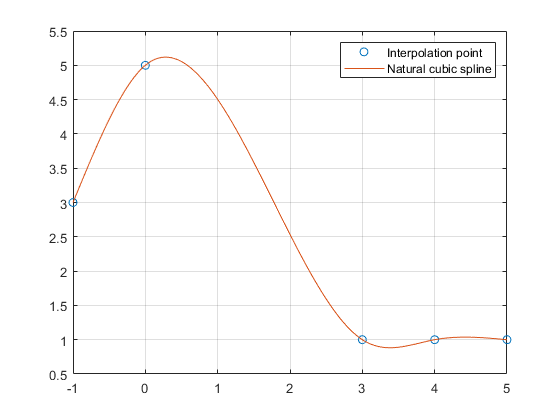

x1 = [x1; x_b(end)];
y1 = [y1; y_b(end)];
plot(x_b,y_b,'o',x1,y1);
grid on;
legend('Interpolation point','Natural cubic spline');

**Also, we can observe that the obtained Natural Cubic Spline curve fits the interpolation points well. So the programme works  correctly.**

# **Appendix**

**The implementation of function *****cos2, polyinterp, newtdd, and splinecoef *****please refer to the attachment for the source code.**